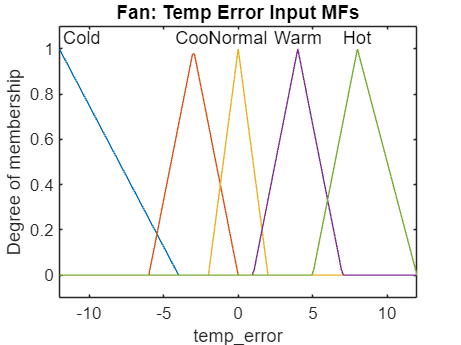

% --- FAN CONTROL (FIS Construction) ---
fisF = mamfis('Name', 'FanControl');

fisF = addInput(fisF, [-12 12], 'Name', 'temp_error');
fisF = addInput(fisF, [-35 35], 'Name', 'hum_error');
fisF = addOutput(fisF, [0 100], 'Name', 'fan');

% Temp MFs
fisF = addMF(fisF, 'temp_error', 'trimf', [-12 -12 -4], 'Name', 'Cold');
fisF = addMF(fisF, 'temp_error', 'trimf', [-6 -3 0],    'Name', 'Cool');
fisF = addMF(fisF, 'temp_error', 'trimf', [-2 0 2],     'Name', 'Normal');
fisF = addMF(fisF, 'temp_error', 'trimf', [1 4 7],      'Name', 'Warm');
fisF = addMF(fisF, 'temp_error', 'trimf', [5 8 12],     'Name', 'Hot');

% Hum MFs
fisF = addMF(fisF, 'hum_error', 'trimf', [-35 -35 -15], 'Name', 'VeryDry');
fisF = addMF(fisF, 'hum_error', 'trimf', [-20 -8 0],    'Name', 'Dry');
fisF = addMF(fisF, 'hum_error', 'trimf', [-6 0 6],      'Name', 'OK');
fisF = addMF(fisF, 'hum_error', 'trimf', [0 10 18],     'Name', 'Humid');
fisF = addMF(fisF, 'hum_error', 'trimf', [15 35 35],    'Name', 'VeryHumid');

% Output MFs
fisF = addMF(fisF, 'fan', 'trimf', [0 0 25],     'Name', 'OFF');
fisF = addMF(fisF, 'fan', 'trimf', [20 40 60],   'Name', 'LOW');
fisF = addMF(fisF, 'fan', 'trimf', [50 70 90],   'Name', 'MED');
fisF = addMF(fisF, 'fan', 'trimf', [80 100 100], 'Name', 'HIGH');

% Rules
fan_rules = [
    "temp_error==Cold => fan=OFF"
    "temp_error==Cool & hum_error==VeryHumid => fan=LOW"
    "temp_error==Cool & hum_error==OK => fan=LOW"
    "temp_error==Normal & hum_error==OK => fan=LOW"
    "temp_error==Normal & hum_error==Dry => fan=LOW"
    "temp_error==Normal & hum_error==VeryDry => fan=MED"
    "temp_error==Warm & hum_error==OK => fan=MED"
    "temp_error==Warm & hum_error==Humid => fan=MED"
    "temp_error==Warm & hum_error==VeryHumid => fan=HIGH"
    "temp_error==Hot => fan=HIGH"
    "hum_error==VeryHumid => fan=MED"
    "hum_error==Humid & temp_error==Hot => fan=HIGH"
];
fisF = addRule(fisF, fan_rules);

% --- VISUALIZATION ---
figure(5); plotmf(fisF, 'input', 1); title('Fan: Temp Error Input MFs');

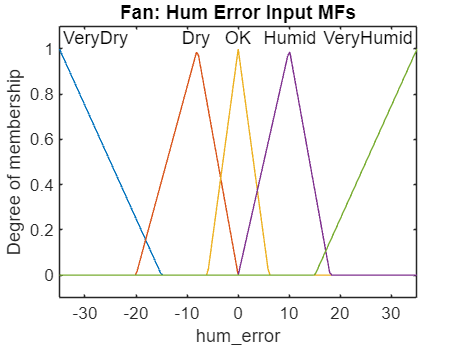

figure(6); plotmf(fisF, 'input', 2); title('Fan: Hum Error Input MFs');

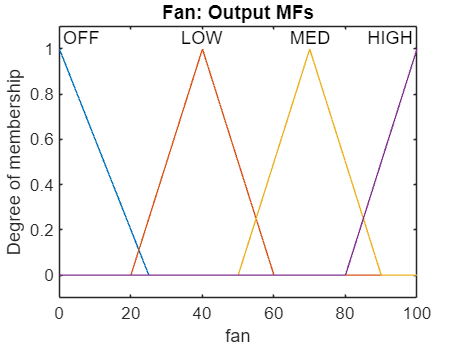

figure(7); plotmf(fisF, 'output', 1); title('Fan: Output MFs');

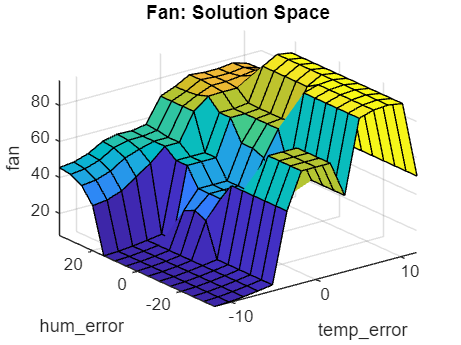

figure(8); gensurf(fisF); title('Fan: Solution Space');